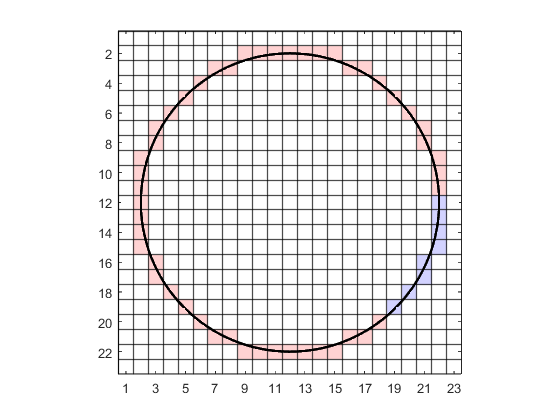

clear

% Circle co-ordinates and colour
cx = 12;
cy = 12;
r = 10;
blue = [210, 210, 255];
red = [255, 210, 210];

% Raster parameters
Nx = 23;
Ny = 23;

% Initialise raster array and calculate pixel co-ordinates
img = uint8(255 * ones(Ny, Nx, 3));

% Draw line
img = drawcircle(img, cx, cy, r, blue, red);

image(img)
hold on
for row = 1 : 1 : Nx
    xline(row-0.5, Color='k', LineWidth=1)
    yline(row-0.5, Color='k', LineWidth=1)
end
theta = 0 : 0.01 : 2 * pi;
x = cx + r * cos(theta);
y = cy + r * sin(theta);
plot(x, y, 'k', LineWidth=2)
hold off

xticks(1:2:Nx)
axis equal
axis([0.5, Nx+0.5, 0.5, Ny+0.5])
exportgraphics(gcf,'../images/midpoint_example.png','Resolution',300) 

function R = drawcircle(R, cx, cy, r, colour1, colour2)

D = 5 - 4 * r;
x = r;
y = 0;
while y <= x
    R(cy+y, cx-x, :) = colour2;
    R(cy-y, cx+x, :) = colour2;
    R(cy-y, cx-x, :) = colour2;
    R(cy+x, cx+y, :) = colour2;
    R(cy+x, cx-y, :) = colour2;
    R(cy-x, cx+y, :) = colour2;
    R(cy-x, cx-y, :) = colour2;
    R(cy+y, cx+x, :) = colour1;

    if D > 0
        D = D - 8 * x + 8 * y + 20;
        x = x - 1;
    else
        D = D + 8 * y + 12;
    end
    y = y + 1;
end

end